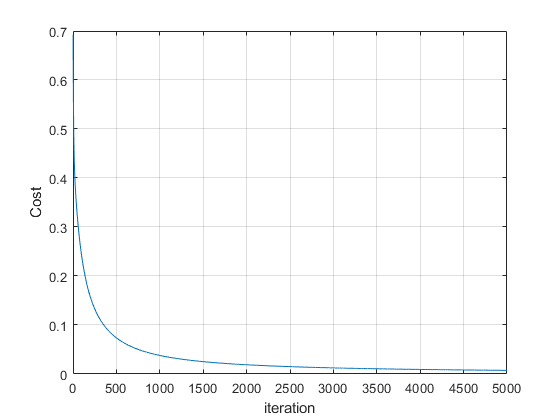

clear all; clc;
x = [0 0 ; 0 1; 1 0; 1 1];
y = [0; 1; 1; 1];

[M, k] = size(x);
X=[ones(M,1),x];
alpha = 0.25;
teration = 5000;

W = zeros(k+1,1)+0.001;
Cost_J = zeros(teration, 1);
for i= 1:teration
    h = sigmoid(X* W);
    error = h-y;
    delta_W = (1/M)*(error' *X);
    
    W = W-(alpha*delta_W');
   Cost_J(i) = (-1/M)*sum(y.*log(h)+(1-y).*log(1-h));
end

plot(Cost_J);
xlabel('iteration');
ylabel('Cost');
grid on 


Prob = round(h);
fprintf('Training Set Acc %.2f%%', mean(double(Prob==y))*100);

Training Set Acc 100.00%

Prob

Prob =      0
     1
     1
     1


W

W =    -4.0952
    9.1178
    9.1178
